fprintf("2.")

2.

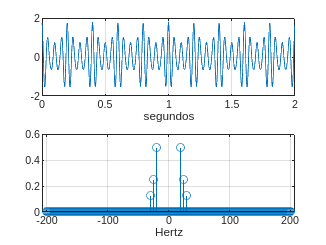

[s, Fa] = exame(1999,2);

fprintf("a)")

a)

T = 0.2;

fprintf("   1) Período: %.1f segundos.", T)

   1) Período: 0.2 segundos.

fprintf("   2) Foram registados 2 segundos de sinal.")

   2) Foram registados 2 segundos de sinal.

fprintf("   3) Soma de 3 sinusoides, com frequências 20, 25 e 30 Hz.")

   3) Soma de 3 sinusoides, com frequências 20, 25 e 30 Hz.

fprintf("b)")

b)

Ta = 1/Fa;
N = 2/Ta;

fprintf("%.0f amostras.",N)

800 amostras.

fa = 400

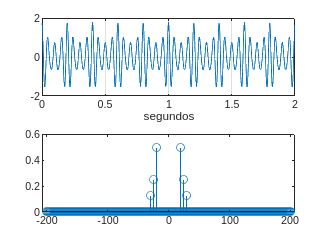

[X,f] = Espetro(s,Ta);

t = (0:N-1) / Fa;                % eixo do tempo
%f = (0:N-1) * (Fa / N) - Fa/2;  % eixo das frequências

fprintf("c)")

c)

subplot(2,1,1)
plot(t,s)
xlabel("Tempo (s)")
ylabel("Amplitude")

subplot(2,1,2)
plot(f,X)

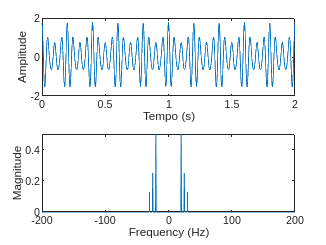

xlabel("Frequency (Hz)")
ylabel("Magnitude")

fprintf("d)")

d)

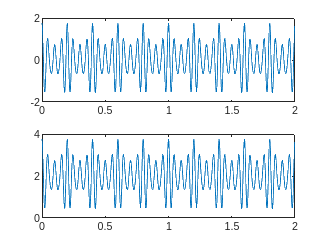

subplot(2,1,1)
s1 = s + 2;
plot(t,s)
subplot(2,1,2)
plot(t,s1)

fprintf("A operação adiciona o valor 2 a cada uma das 800 amostras, aumentando a componente DC por 2. Isto faz com que o centro das sinusoides esteja em 2 e não em 0.")

A operação adiciona o valor 2 a cada uma das 800 amostras, aumentando a componente DC por 2. Isto faz com que o centro das sinusoides esteja em 2 e não em 0.

fprintf("e)")

e)

fprintf("f)")

f)

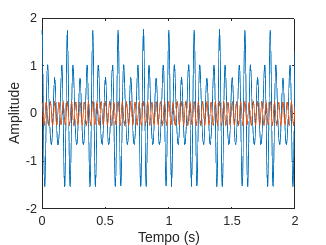


filtro = zeros(1, length(f));
filtro(abs(f)>29) = 1;
Y = X.*filtro;
subplot(1,1,1)
Reconstroi(X,f);
hold on
Reconstroi(Y,f);
xlim([0,2]);